# Notes regarding lab format

We will use Matlab Livescript for this lab. Livescript allows switching between text and code cells. 

You will find the entire lab manual in this file. Some exercises require you to write a text answer, others require you to write code. You should not define functions inside this file. Instead save functions to the functions folder and call them from the code cells in this notebook.

Your finished lab report should be a .zip-file containing the data folder, your functions folder, any output images you might have saved and this livescript file.

Since we need to access the functions and data folder the first step is to add these two locations to MATLAB's path.

addpath('./functions');
addpath('./data');

# Lab 2: Learning and convolutional neural networks

## 2.1 Learning a Linear Classifier

In this part, we will try to learn a linear classifier for blood cell detection. Note that the classifier could also be viewed as a minimal neural network consisting of three parts: a scalar product node (or fully-connected node), a constant (or bias) term and a logistic sigmoid function. To find good parameters we will try to minimize the negative log-likelihood over a small training set.

The output from our classifier is a probability p for the input patch being centered at a cell centre. The sigmoid function will make sure that 0 ≤ p ≤ 1. To be more precise the output is


$$p=\frac{e^y }{1+e^y }\;\;\;\;\textrm{where}\;\;\;\;y=I\cdot \omega +\omega_0$$


Instead of testing a bunch of manually chosen w’s and w_0’s, we will try to learn good values for all the parameters. This requires training examples, that you find in cell_data.mat.

## Ex 2.1 

## Load the data using

load cell_data.mat

It loads a structure, cell_data, with two fields, `fg_patches` and `bg_patches`, corresponding to positive (centered blood cells) negative examples respectively.

## Ex 2.2 

Create two new variables, examples and labels. The variable examples should be a cell structure containing all the patches (both positives and negatives) and labels should be an array with the same number of elements such that `labels(i) = 1` if` examples{i}` is a positive example, and `labels(i) = 0` otherwise.

examples = [cell_data.fg_patches, cell_data.bg_patches];
labels = [zeros(1, size(cell_data.fg_patches, 2)), ones(1, size(cell_data.bg_patches, 2))];

% % Shuffle the two datasets
% rng(1);
% rand_idx = randperm(size(examples, 2));
% examples = examples(rand_idx);
% labels = labels(rand_idx);

## Ex 2.3

Split the data into training,` (examples_train, labels_train)`, and validation,` (examples_val, labels_val)`. The two should have a similar structure to examples and labels. Write on the report which percentage of the data you used for validation.

**Percentage of data used for training**: 80%

**Percentage of data used for validation**: 20%

Since the available dataset is not large (in order of hundreds of elements), and since we are not requiring 3 datasets spits (train, validation **and test**), I believe the ratio 80-20 should be a good compromise.

% Add from the subsets WITHOUT shuffling them first, so that we have more
% "equal distribution" of images from both classes.
train_perc = 0.8;

% FG data (non blood cells)
train_size = int32(size(cell_data.fg_patches, 2) * train_perc);
train_fg = cell_data.fg_patches(1:train_size);
train_labels_fg = zeros(1, size(train_fg, 2));
val_fg = cell_data.fg_patches(train_size+1:end);
val_labels_fg = zeros(1, size(val_fg, 2));

% BG data (blood cells)
train_size = int32(size(cell_data.bg_patches, 2) * train_perc);
train_bg = cell_data.bg_patches(1:train_size);
train_labels_bg = ones(1, size(train_bg, 2));
val_bg = cell_data.bg_patches(train_size+1:end);
val_labels_bg = ones(1, size(val_bg, 2));

examples_train = [train_bg, train_fg];
examples_val = [val_bg, val_fg];
labels_train = [train_labels_bg, train_labels_fg];
labels_val = [val_labels_bg, val_labels_fg];
% 
% idx = 39;
% disp(['label:' num2str(labels_val(idx))])
% figure, colormap gray, imshow(cell2mat(examples_val(idx)))

% % NOTE: The cells have been previously shuffled, so there will be both bg
% % and fg patches in the slices.
% train_perc = 0.6;
% val_perc = 0.2;
% test_perc = 0.2;
% 
% train_size = int32(size(examples, 2) * train_perc);
% val_size = int32(size(examples, 2) * val_perc);
% test_size = int32(size(examples, 2) * test_perc);
% 
% examples_train = examples(1:train_size);
% examples_val = examples(train_size+1:train_size+val_size);
% examples_test = examples(train_size+val_size+1:train_size+val_size+test_size);
% 
% labels_train = labels(1:train_size);
% labels_val = labels(train_size+1:train_size+val_size);
% labels_test = labels(train_size+val_size+1:train_size+val_size+test_size);
% 
% % NOTE: The following is left for future reference, please ignore it.
% % Helper anonymous function to slice cell array x from a to b into a 3D matrix. 
% % slice = @(x, a, b) permute(cat(3, x{a:b}), [3, 1, 2]);
% % slice = @(x, a, b) cat(3, x{a:b}); % size: (35 x 35 x N)

## 2.2 Training the classifier

We will try to find parameters that minimize the negative log-likelihood on the training data. More precisely,


$$L\left(\theta \right)=\sum_{i\in S_+ } -\ln \left(p_i \right)+\sum_{i\in S_- } -\ln \left(1-p_i \right)=\sum_i L_i \left(\theta \right)$$


where $p_i$ refers to the classifier output for the ith training example. As in the lectures we will refer to the

terms here as the partial loss $L_i$.

Before doing the next exercise, you need to work out how to compute the gradient of the partial loss $L_i$.

## Ex 2.4

Make a function

        `[wgrad, w0grad] = partial_gradient(w, w0, example_train, label_train)`

that computes the derivatives of the partial loss L_i with respect to each of the classifier parameters. Let the output wgrad be an array of the same size as the weight image, w (and let w0grad be a number). 

At each iteration of stochastic gradient descent, a training example, i, is chosen at random. For this example the gradient of the partial loss, L_i , is computed and the parameters are updated according to this gradient. The most common way to introduce the randomness is to make a random reordering of the data and then going through it in the new order. One pass through the data is called an epoch.

## Ex 2.5

Make a function

        `[w, w0] = process_epoch(w, w0, lrate, examples_train, labels_train)`

that performs one epoch of stochastic gradient descent

## Ex 2.6 

Initialize `w = s * randn(35,35);`, with `s = 0.01` and `w0 = 0;` and run 5 epochs on your training examples. Plot w after each epoch (or after each iteration if you are curious), to get a sense of what is happening. Also, try using different `s={10,1,0.1}` and plot w after 5 epochs for each value of s. Include on the report visualizations of w for the different values of s, along with an written explanation of what is happening.

------------------------------------------


s value: 0.01


Initial w: 


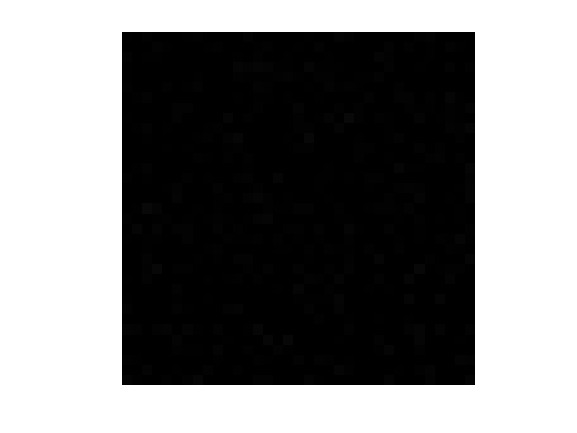

Epoch n.1


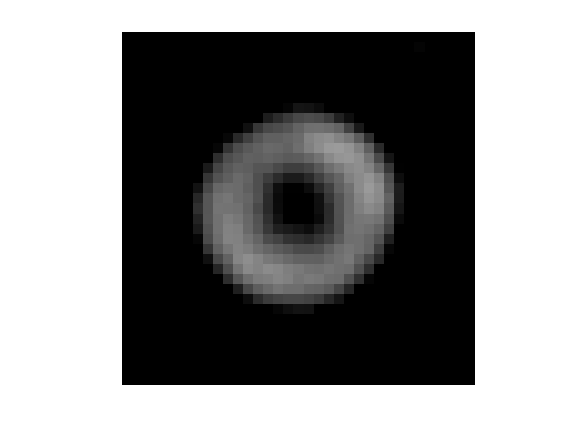

Epoch n.2


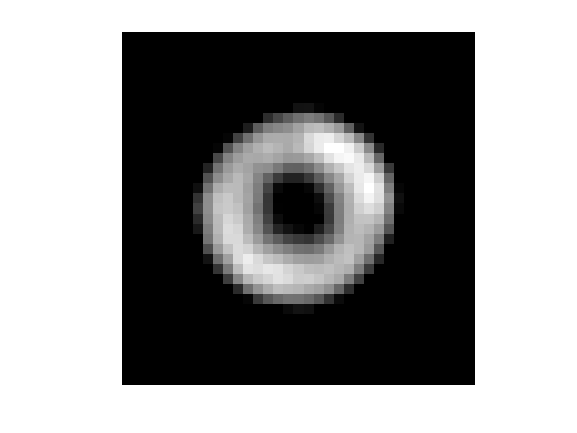

Epoch n.3


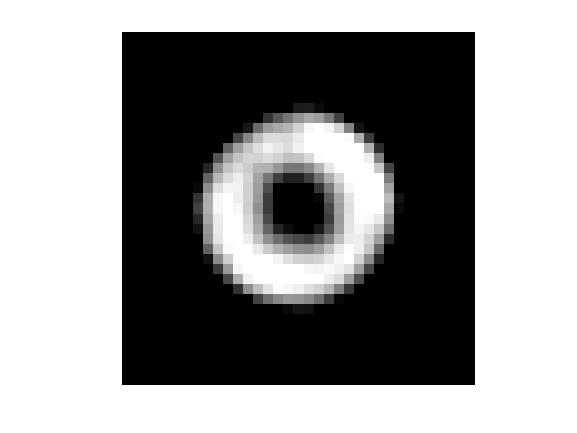

Epoch n.4


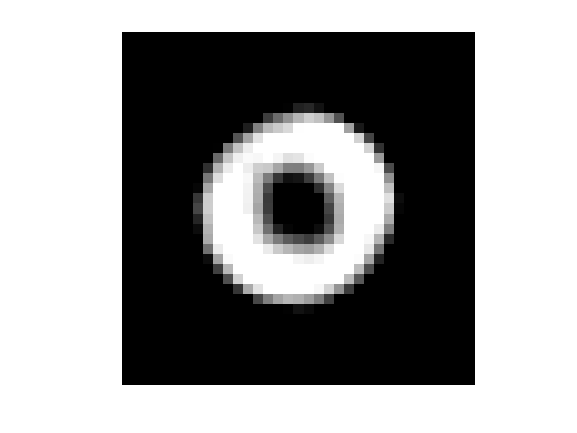

Epoch n.5


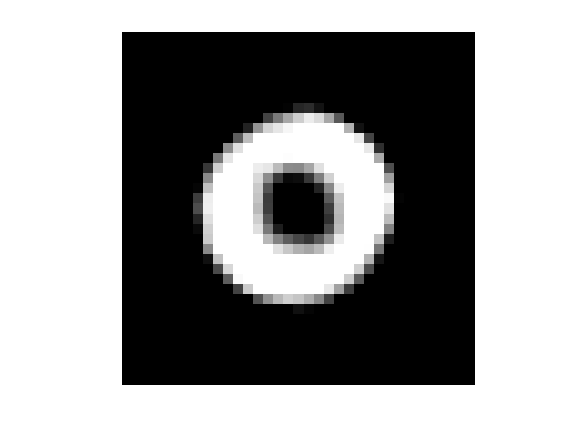

Final w:


------------------------------------------


s value: 10


Initial w: 


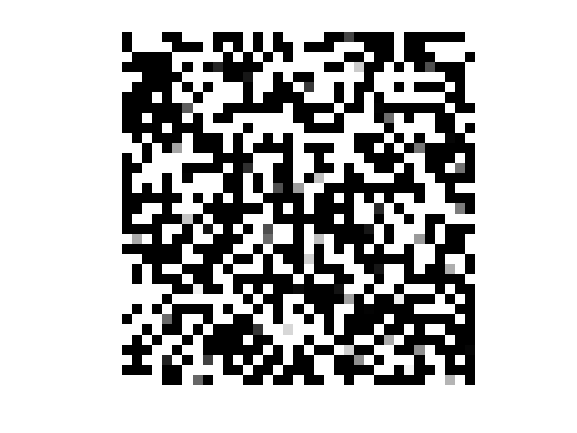

Final w:


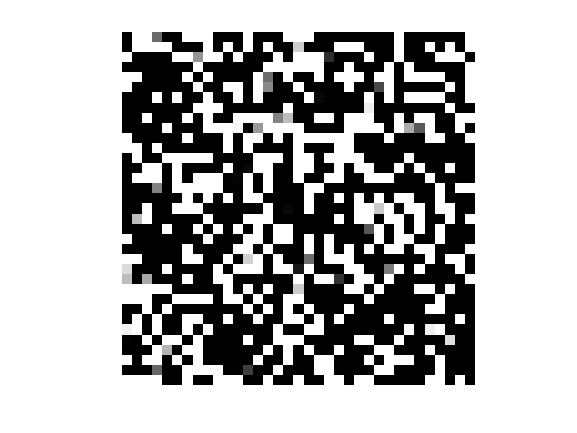

------------------------------------------


s value: 1


Initial w: 


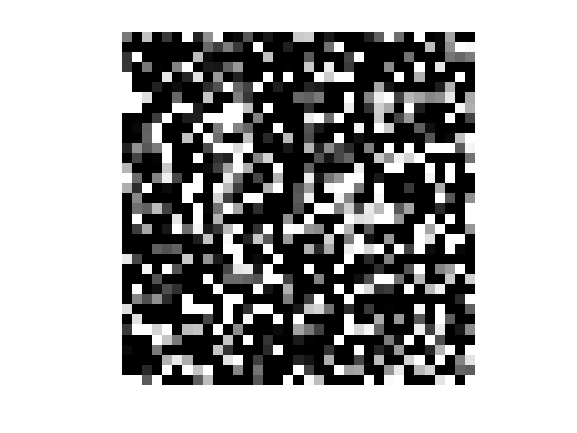

Final w:


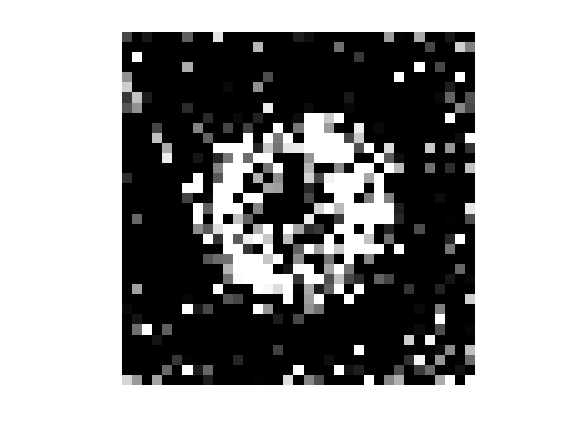

------------------------------------------


s value: 0.1


Initial w: 


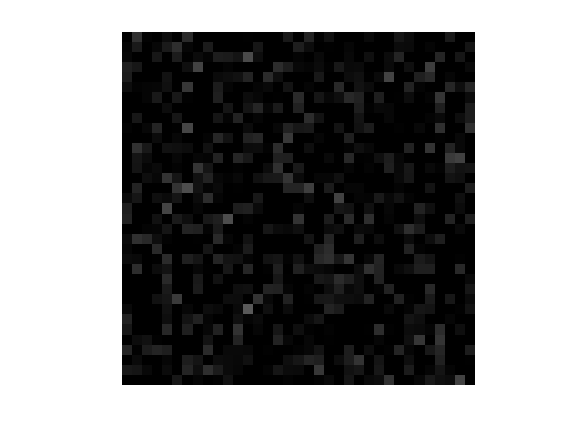

Final w:


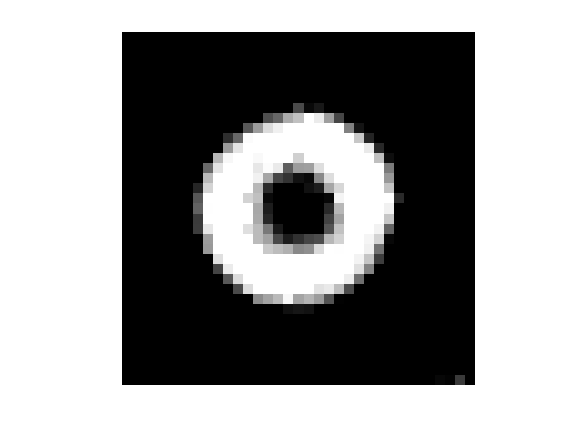

lrate = 0.1;
epochs = 5;
for s = [0.01, 10, 1, 0.1]
    w = s * randn(35, 35);
    w0 = 0;
    disp(['------------------------------------------'])
    disp(['s value: ' num2str(s)])
    disp(['Initial w: ']), figure, colormap gray, imshow(w)
    for n = 1:epochs
        [w, w0] = process_epoch(w, w0, lrate, examples_train, labels_train);
        if s == 0.01
            disp(['Epoch n.' num2str(n)]), figure, colormap gray, imshow(w)
        end
    end
    disp(['Final w:']), figure, colormap gray, imshow(w)
end

**Your written answer here:**

The value of s is controlling the pixel intensity acting as a scaler for the intire w matrix. While training, the elements of w gets updated according to their gradient w.r.t. the training data.

In particular, the gradient of w depends on the classifier output, which in turn depends on w. Because of that, small initial values of w will tend to generate small gradient values and therefore lead to a "smoother" update of w. In theory, the steps of the gradients are small enough to get closer and closer to the local minimum, rather than escaping it when the gradients are large.

In practice, w update is showed in the above pictures: small values of s generate smoother transitions compared to large s values.

## Exercise 2.7

As said before, at each iteration of stochastic gradient descent, a training example is chosen at random. Check what happens to w after 5 epochs when that training example is not chosen randomly but in sequence, i.e. first `i = 1`, then `i = 2`, and so on. Include on the report a visualization of w for this case. (Don’t forget to change back your function to a random choice of i after this exercise).

You can display the resulting filters inside this livescript notebook using the function imagesc.

------------------------------------------


s value: 0.01


Final w:


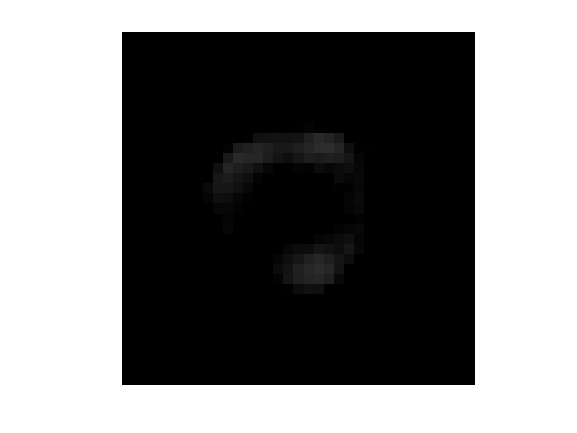

------------------------------------------


s value: 10


Final w:


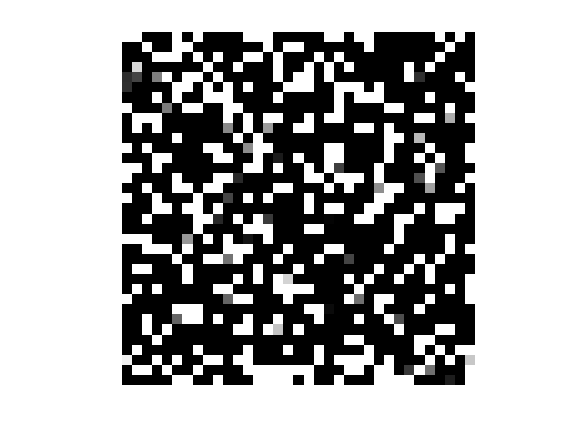

------------------------------------------


s value: 1


Final w:


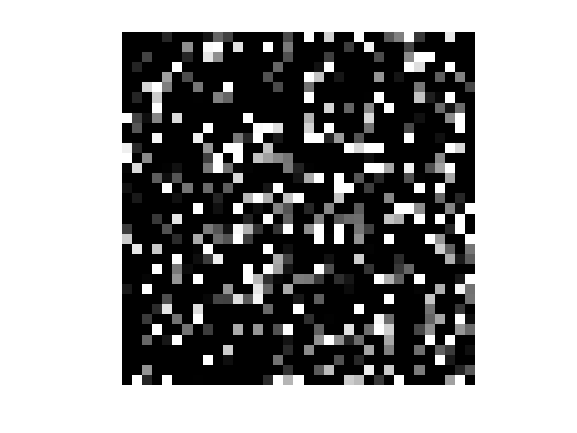

------------------------------------------


s value: 0.1


Final w:


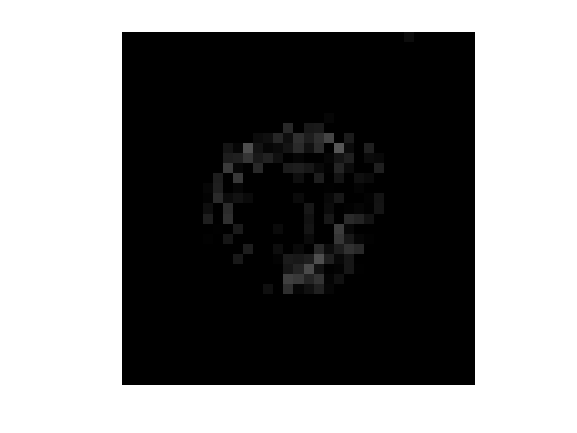

run_sequential = true;
lrate = 0.1;
for s = [0.01, 10, 1, 0.1]
    w = s * randn(35, 35);
    w0 = 0;
    disp(['------------------------------------------'])
    disp(['s value: ' num2str(s)])
    for n = 1:epochs
        [w, w0] = process_epoch(w, w0, lrate, examples_train, labels_train, run_sequential);
    end
    disp(['Final w:']), figure, colormap gray, imshow(w)
end

## Ex 2.8 

Make a function

        `predicted_labels = classify(examples_val,w,w0);`

that applies the classifier to the example data. After that, use it on `examples_train` and examples_val and check how much accuracy it gets for each by comparing the predicted labels with `labels_train` and `labels_val` respectively. Write on your report the highest accuracy you were able to achieve in the training and validation data. Hint: train the classifier for longer than 5 epochs to make sure that it converges.

When you have defined the function run the following code.

Final w:


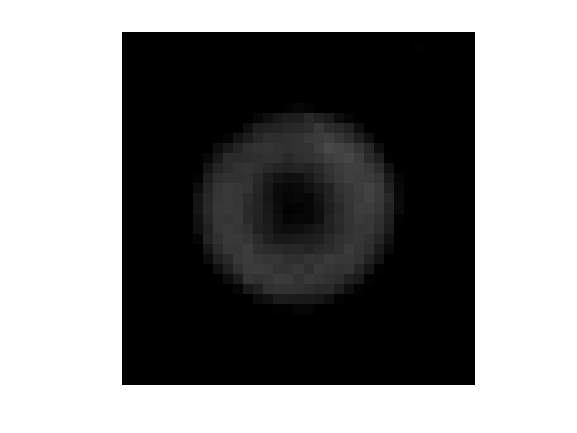

rng(1); % Set a random seed in order to make results reproducible.

lrate = 0.0001;
epochs = 400;
s = 0.01;
w = s * randn(35, 35);
w0 = 0;
for n = 1:epochs
    [w, w0] = process_epoch(w, w0, lrate, examples_train, labels_train);
end
disp(['Final w:']), figure, colormap gray, imshow(w)


predicted_labels = classify(examples_train, w, w0);
correct = sum(predicted_labels == labels_train);
accuracy = 100 * correct / length(labels_train);
fprintf(["Training Accuracy: "] + accuracy + ["%%"])

Training Accuracy: 85.625%

predicted_labels = classify(examples_val, w, w0);
correct = sum(predicted_labels == labels_val);
accuracy = 100 * correct / length(labels_val);
fprintf(["Validation Accuracy: "] + accuracy + ["%%"])

Validation Accuracy: 83.75%

**Write the highest accuracy you were able to get here:**

Test accuracy of **83.75%** with parameters:

- epochs: 400

- learning rate: 0.0001

- s: 0.01

- rng(1) ("random seed")

## Ex 2.9

The data for training this classifier consists on only 400 examples (less if you consider that you have split it into training and validation). To achieve higher accuracy it might be useful to perform some data augmentation before the training. In this exercise you will increase the number of elements in the training examples by M times. Make a function

        `[examples_train_aug,labels_train_aug] = augment_data(examples_train,labels_train,M)`

that takes each sample of the original training data and applies M random rotations (you can use Matlab function imrotate), from which result M new examples. Store these new examples in examples_train_aug and their corresponding labels in labels_train_aug. Train the classifier with this augmented data and write on your report the new values for accuracy on the training and validation examples.

INFO. Original image n.2


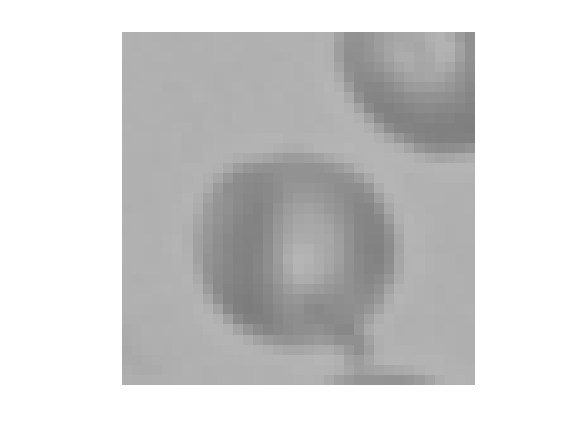

INFO. Augmented image n.2, rotated with angle: 90


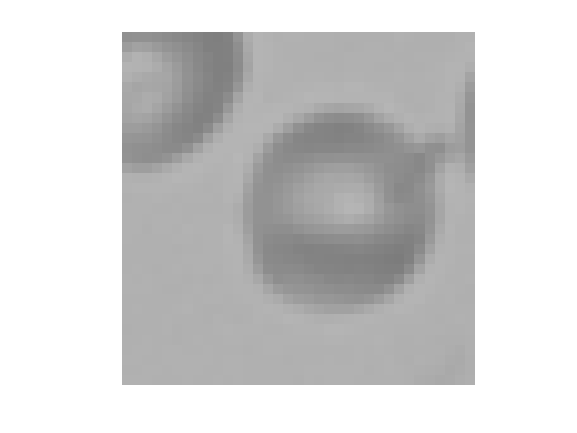

INFO. Augmented image n.3, rotated with angle: 180


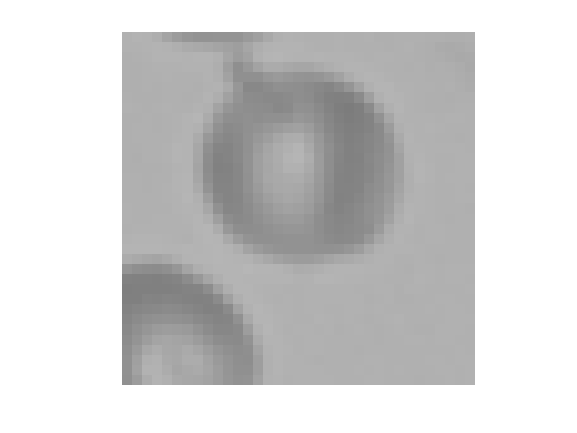

INFO. Augmented image n.4, rotated with angle: 180


INFO. Augmented image n.5, rotated with angle: 270


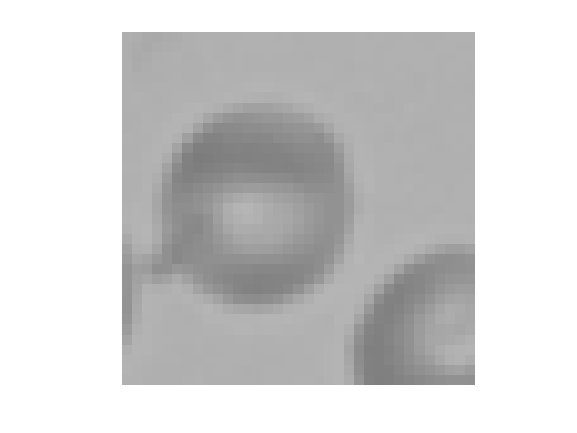

rng(1); % Set a random seed in order to make results reproducible.

M = 4;
apply_scaling = false;
[examples_train_aug, labels_train_aug] = augment_data(examples_train, labels_train, M, apply_scaling);

Final w:


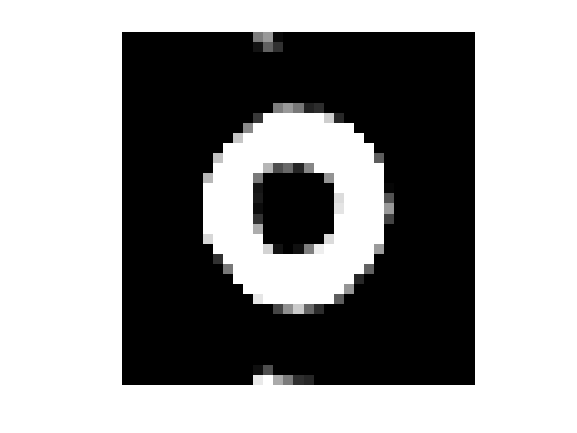

lrate = 0.01;
epochs = 100;
s = 0.1;
w = s * randn(35, 35);
w0 = 0;
for n = 1:epochs
    [w, w0] = process_epoch(w, w0, lrate, examples_train_aug, labels_train_aug);
end
disp(['Final w:']), figure, colormap gray, imshow(w)

predicted_labels = classify(examples_train_aug, w, w0);
correct = sum(predicted_labels == labels_train_aug);
accuracy = 100 * correct / length(labels_train_aug);
fprintf(["Training Accuracy: "] + accuracy + ["%%"])

Training Accuracy: 91.0226%

predicted_labels = classify(examples_val, w, w0);
correct = sum(predicted_labels == labels_val);
accuracy = 100 * correct / length(labels_val);
fprintf(["Validation Accuracy: "] + accuracy + ["%%"])

Validation Accuracy: 93.75%

**Write the highest accuracy you were able to get here:**

Test accuracy of **93.75%** with parameters:

- epochs: 100

- learning rate: 0.01

- s: 0.1

- rng(1) ("random seed")

## 2.3 Convolutional neural networks

In the last part, your task is to train convolutional neural networks using Matlab.

## `Ex 2.10 `

Run the following cell

[imgs, labels] = digitTrain4DArrayData;

to load a dataset of images of digits into Matlab. You will find the 5000 digit images in imgs. Plot a few

of them to see what the data looks like.

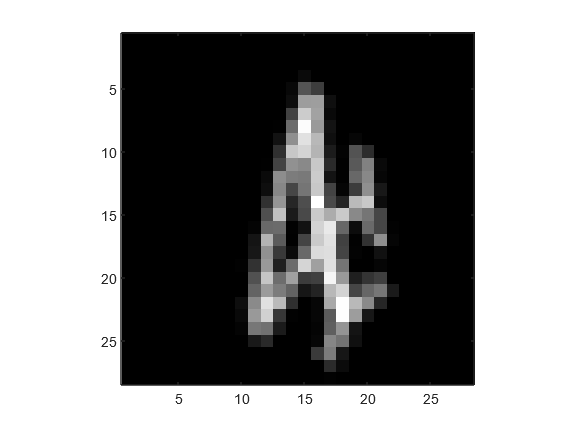

N = 3214; % We have 5000 images so any number between 1 and 5000 works.
img = imgs(:,:,:,N);
imagesc(img), axis image, colormap gray

The next step is to define a network for classification. In Matlab, you do this by simply giving an array of the layers. For example, this would be a linear classifier similar to the one you trained for cells:

        layers = [

            imageInputLayer([35 35 1]);

            fullyConnectedLayer(1);

            softmaxLayer();

            classificationLayer()];

## Ex 2.11 

Make a function

        `layers = basic_cnn_classifier()`

that implements the following network in Matlab:

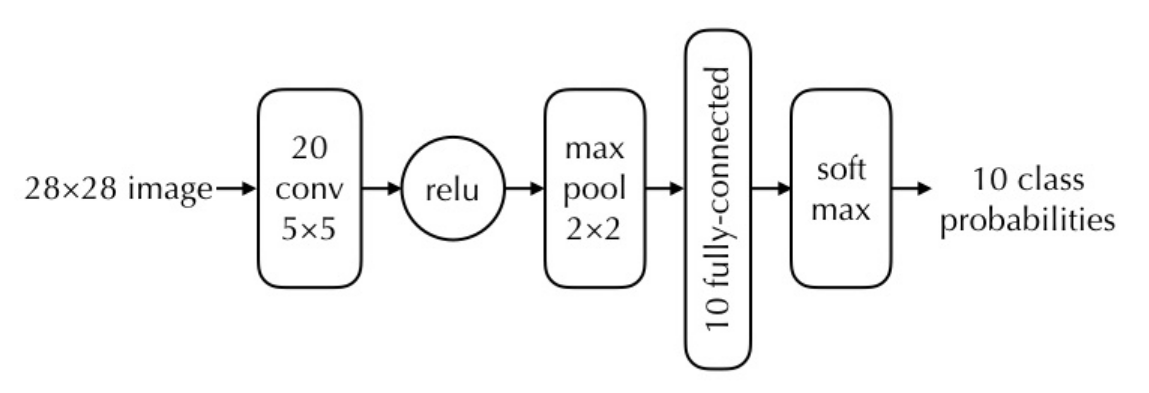

Apart from the layers above the functions `convolution2dLayer`, `reluLayer` and `maxPooling2dLayer` will be useful. Note that you have to set the *stride* for max pooling to 2 to get the expected downsampling.

When you have written the function run the following cell:

layers = basic_cnn_classifier()

layers =   7×1 Layer array with layers:

     1   ''   Image Input             28×28×1 images with 'zerocenter' normalization
     2   ''   Convolution             20 5×5 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   ReLU                    ReLU
     4   ''   Max Pooling             2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''   Fully Connected         10 fully connected layer
     6   ''   Softmax                 softmax
     7   ''   Classification Output   crossentropyex

## Ex 2.12 

Create a set of training options telling Matlab to use stochastic gradient descent with momentum (SGDM), for the optimization:

        `options = trainingOptions(’sgdm’);`

Now train the network (using default parameters) by running

        net = trainNetwork(imgs, labels, layers, options)

options = trainingOptions('sgdm');
net = trainNetwork(imgs, labels, layers, options);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |        7.03% |       2.3176 |          0.0100 |
|       2 |          50 |       00:00:01 |       47.66% |       1.7610 |          0.0100 |
|       3 |         100 |       00:00:02 |       59.38% |       1.1693 |          0.0100 |
|       4 |         150 |       00:00:03 |       64.84% |       1.0554 |          0.0100 |
|       6 |         200 |       00:00:04 |       77.34% |       0.7596 |          0.0100 |
|       7 |         250 |       00:00:06 |       78.12% |       0.7429 |          0.0100 |
|       8 |         300 |  

## Ex 2.13 

Try the network on a few of the training images. You can use `net.predict(img)` to get the ten output probabilities or `net.classify(img)` to get the most probable class.

N = 3214;
img = imgs(:,:,:,N);
net.predict(img)

ans = 1×10 single row vector
    0.0000    0.0001    0.0000    0.0001    0.9996    0.0000    0.0000    0.0000    0.0001    0.0000


net.classify(img)

ans = categorical
     4 


acc_count = nnz(net.classify(imgs) == labels); 
acc = acc_count / length(labels);
disp(['INFO. Network accuracy: ' num2str(acc * 100) '%%'])

INFO. Network accuracy: 99.72%%


## Ex 2.14 

Work out how many trainable parameters your network contains. Include the answer in your submission. If you explore what the data structure net actually contains, you can find the answer there as well. Note that the convolution layer does not use padding so the output from the convolution layer is smaller than the input.

**Write your answer here:**

- CONV: since the input image has only one channel, we have (5 * 5 + 1) * 20 = 520 parameters (the +1 is the bias)

- FC: it depends on the number of input features and the number of output output features. Because of the convolution and max pooling, the input volume is: 2880. Hence, the number of neurons is 2880 * 10 + 10 = 288010 (the +10 is the bias)

Total: CONV+FC = 288530

for l = 1:length(net.Layers)
    if isprop(net.Layers(l), 'Weights') % Does layer l have weights?
        disp(['INFO. Layer ' net.Layers(l).Name ' parameters:']);
        disp(size(net.Layers(l).Weights));
    end
end

INFO. Layer conv parameters:


     5     5     1    20



INFO. Layer fc parameters:


          10        2880



## Ex 2.15 

Matlab prints a lot of output, for example the accuracy on the training set. Recall from the lectures that this number is not very good for judging the quality of a classifier. Instead we should save a subset of the data as a validation set, that we can use to evaluate the trained network. 

Divide the data into training `imgs` and `labels` into new variables `imgs_train, labels_train, imgs_val, labels_val`.

train_perc = 0.8;
val_perc = 0.2;

train_size = int32(size(imgs, 4) * train_perc);
val_size = int32(size(imgs, 4) * val_perc);

imgs_train = imgs(:, :, :, 1:train_size);
labels_train = labels(1:train_size);
imgs_val = imgs(:, :, :, train_size+1:end);
labels_val = labels(train_size+1:end);

Make a function 

        `net = train_classifier(layers, imgs_train, labels_train, imgs_val, labels_val) `

that runs a few epochs of training and then evaluates the accuracy on the validation set. In this case, Matlab has given us a separate test set, so we don’t have to save images for that purpose. *Matlab hints:* You can run multiple images at once by stacking them along the fourth dimension. If you want to continue training the same network you can run

        `net = train_classifier(net.Layers, imgs_train, labels_train, imgs_val, labels_val)`

net = train_classifier(layers, imgs_train, labels_train, imgs_val, labels_val);

INFO. Training network for 20 epochs.
INFO. Network accuracy: 93.2%%


net = train_classifier(net.Layers, imgs_train, labels_train, imgs_val, labels_val);

INFO. Training network for 20 epochs.
INFO. Network accuracy: 97.4%%


**Ex 2.16 **

To run a convolutional neural network we have to perform a massive amount of computations. Hence it is very important to consider the computational load when designing a network. For the network below, compare (roughly) the time consumption of the blue and the red layers. You can ignore effects of padding. Include your answer and your motivation in your submission.

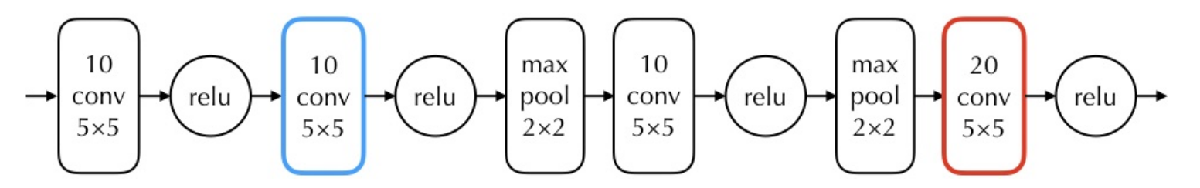

**Write your answer here:**

I can refer to the work of Abuzaid et al., *"Caffe con Troll: Shallow Ideas to Speed Up Deep Learning"*, in particular to Figure 4. Its table reports the different costs of tranforming the convolutional operation into a matrix-matrix multiplicaiton.

In particular, if one focuses on number of FLOPs in Lowering 1 (the first one proposed), one can see that it depends on the output dimension (which depends on the input size) and on the number of filters, i.e. number of output channels.

Since I don't know the exact input size, required to determine the output size, I can roughly estimate the FLOPs, and in turn the computational, based on the number of filters. Because of that, the red convolutional layer should roughly require twice as much time compared to the blue one.

However, the max pooling operation reduces the input size of volume entering the convolutional layer. Since there are 2 max pooling layers and a conv layer with small parameters in between, the input size to the red conv layer might not be as large. Because of that, the computation of the red conv might actually be similar to the blue one.

As a remark, the number of parameters is roughly one double the other:

- blue CONV parameters: (10 * 5 * 5 + 1) * 10 = 2510

- red CONV parameters: (10 * 5 * 5 + 1) * 20 = 5020

So the memory can indeed become a bottleneck when computing the red conv layer.

NOTE: You are not supposed to actually implement and train this network.

## Ex 2.17

Replace the blue box of the network in the figure above by a sequence of two layers of 10 3 × 3 convolutional filters. What changes in terms of network parameters, time consumption and accuracy?

**Write your answer here:**

The number of parameters in the two layers in less than the original layer, therefore the overall number of network parameters decreases:

- number of parameters of the one blue layer: (10 * 5 * 5 + 1) * 10 = 2510

- number of parameters of the two layers: 2 * (10 * 3* 3 + 1) * 10 = 1820

Time consumption:

- Having smaller filters, the resulting weight matrixes during computation would be smaller and therefore faster, roughly: 5 * 5 / (2 * 3 * 3)

Accuracy:

- It would become deeper, which is usually beneficial in terms of accuracy. However, not having pooling nor relu layers might negatively impact the network accuracy.

## Ex. 2.18

Make a copy of basic_cnn_classifier.m and name it better_cnn_classifier.m. Try modifying the network by adding more layers. Also experiment with the training options. How much can you improve the results? Include precision and recall for the alternative network in your submission.

layers = better_cnn_classifier();
net = train_classifier(layers, imgs_train, labels_train, imgs_val, labels_val);

INFO. Training network for 20 epochs.
INFO. Network accuracy: 99.3%%


## Ex 2.19 

Load the builtin test images using

        `[imgs_test, labels_test] = digitTest4DArrayData;`

Run the network on all the test images. You apply the network to an image using

        pred = net.classify(image)

Compute precision and recall for each of the 10 classes and include these in your submission. The definitions of precision and recall can be found in the lecture notes chapter 4.

[imgs_test, labels_test] = digitTest4DArrayData;
predictions = net.classify(imgs_test);
for class = 0:9
    labels_class_idx = labels_test == num2str(class);
    correct_predictions = nnz(predictions(labels_class_idx) == num2str(class));
    precision = correct_predictions / nnz(predictions == num2str(class));
    recall = correct_predictions / length(labels_test(labels_class_idx));
    disp(['INFO. Precision for digit ' num2str(class) ': ' num2str(precision)]);
    disp(['INFO. Recall for digit ' num2str(class) ':    ' num2str(recall)]);
    disp('------------------------------------------------');
end

INFO. Precision for digit 0: 1


INFO. Recall for digit 0:    0.984


------------------------------------------------


INFO. Precision for digit 1: 0.98778


INFO. Recall for digit 1:    0.97


------------------------------------------------


INFO. Precision for digit 2: 0.99004


INFO. Recall for digit 2:    0.994


------------------------------------------------


INFO. Precision for digit 3: 0.97271


INFO. Recall for digit 3:    0.998


------------------------------------------------


INFO. Precision for digit 4: 0.998


INFO. Recall for digit 4:    1


------------------------------------------------


INFO. Precision for digit 5: 0.996


INFO. Recall for digit 5:    0.996


------------------------------------------------


INFO. Precision for digit 6: 1


INFO. Recall for digit 6:    0.994


------------------------------------------------


INFO. Precision for digit 7: 0.99398


INFO. Recall for digit 7:    0.99


------------------------------------------------


INFO. Precision for digit 8: 0.9881


INFO. Recall for digit 8:    0.996


------------------------------------------------


INFO. Precision for digit 9: 0.99402


INFO. Recall for digit 9:    0.998


------------------------------------------------


## Ex 2.20

Save three of the failure cases with names indicating what digit they were mistaken for. Include these in your submission. You can use imwrite(img, ’mistaken_as_5.png’) to save an image if it is correctly scaled. Have a look at the file before submitting it, so it looks right.

You can load and display the images here using imagesc:

INFO. Image mistaken as 3:


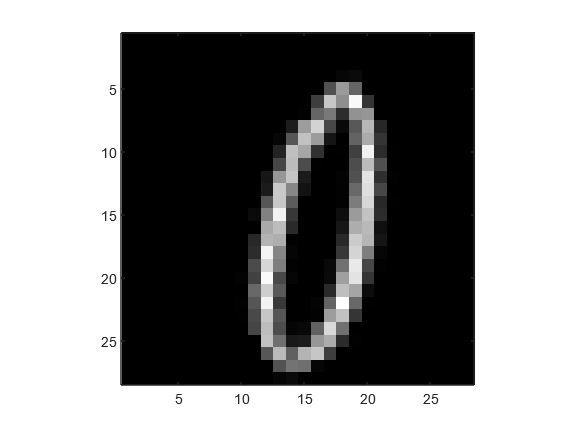

INFO. Image mistaken as 9:


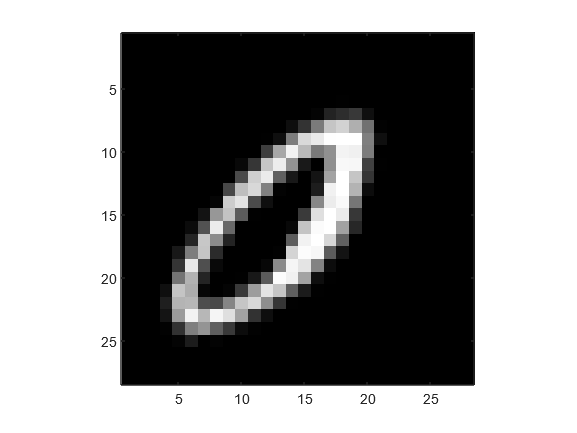

INFO. Image mistaken as 8:


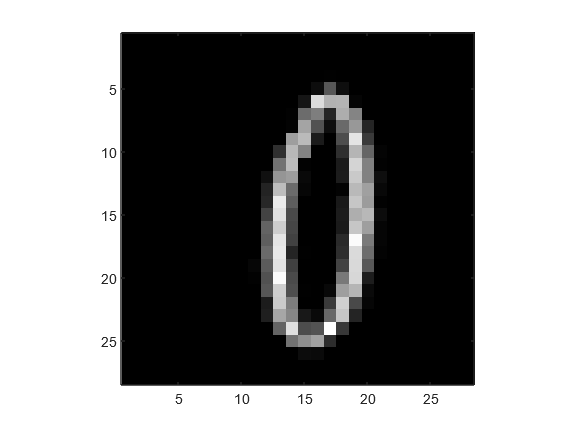

% Get all the indeces of the failing predictions.
fail_idx = predictions ~= labels_test;
fail_imgs = imgs_test(:, :, :, fail_idx);
fail_labels = predictions(fail_idx);
% Loop over the first three mislabeled images.
for n = 1:3
    disp(['INFO. Image mistaken as ' char(fail_labels(n)) ':'])
    figure, imagesc(fail_imgs(:, :, :, n)), axis image, colormap gray
    % Saving image
    filename = strcat('./data/img', num2str(n), '_mistaken_as_', string(fail_labels(n)), '.png');
    imwrite(fail_imgs(:, :, :, n), filename);
end